# Group Project: Virtual MRI Scanner

# Phantom Creation

function matrix = generatePhantoms(size, ellipses, addRectangle)
    matrix = phantom(ellipses, size);

    % Adds a rectangle to the matrix by defining a rectangular region in
    % which the signal intensity for pixels in this region is set appropriately
    if addRectangle == true
        [x, y] = deal(size);
        midX = x / 2;
        deltaX = x / 15;
        leftXBoundary = midX - deltaX;
        rightXBoundary= midX + deltaX;
    
        midY = y / 2;
        deltaY = y / 3.5;
        topYBoundary = midY - deltaY;
        bottomYBoundary= midY + deltaY;

        for i=1:x
            for j=1:y
                % Ensure current coordinate is within the rectangle's boundaries
                if (j >= leftXBoundary) && (j <= rightXBoundary) && (i >= topYBoundary) && (i <= bottomYBoundary)
                    matrix(i, j) = 1;
                end
            end
        end
    end
    figure, imshow(matrix)
end

phantomOne = [0.5 0.75 0.75 0 0 0];   % Outer circle ellipse (rectangle region added below)


phantomTwo = [0.5 0.75  0.75   0    0 0 % Outer circle ellipse
              1.0 0.20  0.20   0.5  0 0 % Right most inner circle ellipse
              1.0 0.15  0.15   0.1  0 0 % Second from right circle ellipse
              1.0 0.10  0.10  -0.2  0 0 % Third from right circle ellipse
              1.0 0.05  0.05  -0.4  0 0 % Fourth from right circle ellipse
              1.0 0.025 0.025 -0.52 0 0 % Left most inner circle ellipse
             ];

% Set size
N = 1024;

% Generate phantoms
disp("Phantom One")

Phantom One


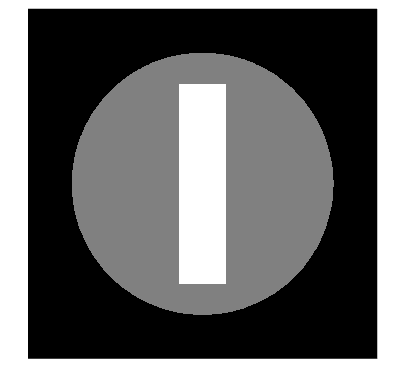

matrixOne = generatePhantoms(N, phantomOne, true);


disp("Phantom Two")

Phantom Two


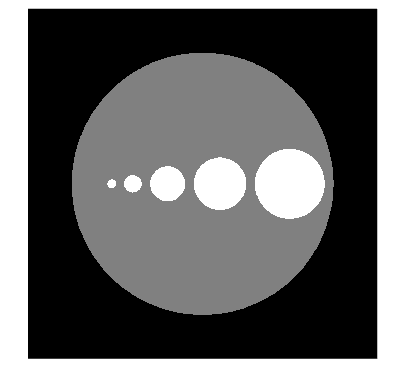

matrixTwo = generatePhantoms(N, phantomTwo, false);

# Graphical User Interface Setup

% Options to select an acquisition trajectory (Cartesian or Radial)
% Sub options to tune data acquisition parameters

# Image Reconstruction

% Set acquisition trajectories according to parameters and display